X = X_air_sg_01;
data = X(1:num_train, :);
label = y(1:num_train);

% Common parameter settings
opts.k  = 5;      % Number of k in K-nearest neighbor
opts.N  = 20;     % number of solutions
opts.T  = 200;    % maximum number of iterations
% Parameters of PSO
opts.CR  = 0.8;      % crossover rate
opts.MR  = 0.01;     % mutation rate
opts.Ts  = 3;        % tournament size (only for 'gat')

% Ratio of validation data
ho = 0.2;
% Divide data into training and validation sets
HO = cvpartition(label,'HoldOut',ho); 
opts.Model = HO; 

% Perform feature selection 
FS = jfs('ga',data,label,opts);


Generation 2 Best (GA)= 0.004663
Generation 3 Best (GA)= 0.004456
Generation 4 Best (GA)= 0.004249
Generation 5 Best (GA)= 0.004249
Generation 6 Best (GA)= 0.004119
Generation 7 Best (GA)= 0.004119
Generation 8 Best (GA)= 0.004093
Generation 9 Best (GA)= 0.003990
Generation 10 Best (GA)= 0.003912
Generation 11 Best (GA)= 0.003782
Generation 12 Best (GA)= 0.003653
Generation 13 Best (GA)= 0.003627
Generation 14 Best (GA)= 0.003601
Generation 15 Best (GA)= 0.003601
Generation 16 Best (GA)= 0.003549
Generation 17 Best (GA)= 0.003497
Generation 18 Best (GA)= 0.003394
Generation 19 Best (GA)= 0.003394
Generation 20 Best (GA)= 0.003394
Generation 21 Best (GA)= 0.003342
Generation 22 Best (GA)= 0.003238
Generation 23 Best (GA)= 0.003161
Generation 24 Best (GA)= 0.003109
Generation 25 Best (GA)= 0.003109
Generation 26 Best (GA)= 0.003005
Generation 27 Best (GA)= 0.003005
Generation 28 Best (GA)= 0.003005
Generation 29 Best (GA)= 0.002953
Generation 30 Best (GA)= 0.002953
Generation 31 Best (G


% Define index of selected features
sf_idx = FS.sf

sf_idx =      5    36    61    81    91   107   112   127   129   136   196   232   252   255   271   287   300   332   340   347   350



% Accuracy  
Acc = jknn(data(:,sf_idx),label,opts); 


 Accuracy: 100 %

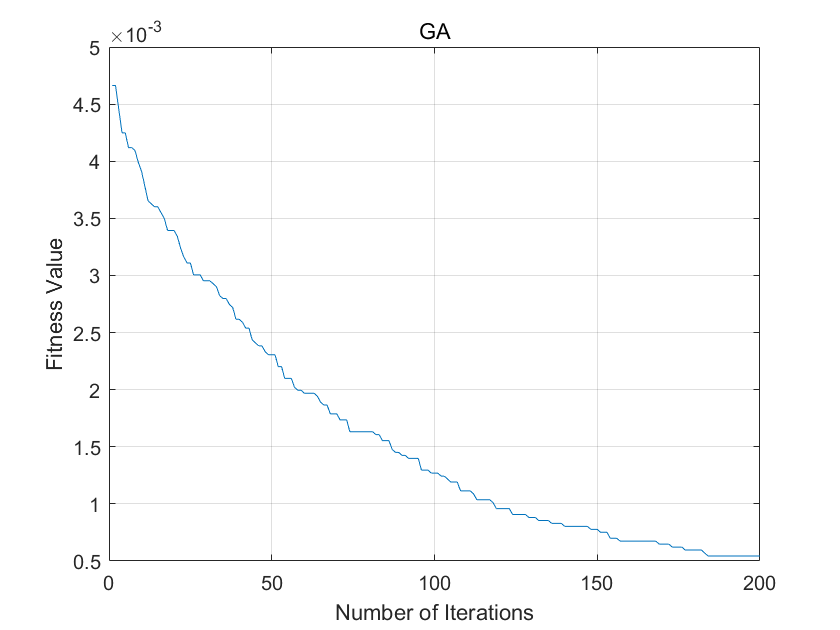


% Plot convergence
plot(FS.c); grid on;
xlabel('Number of Iterations'); 
ylabel('Fitness Value');
title('GA');

vsel_ga = sf_idx;